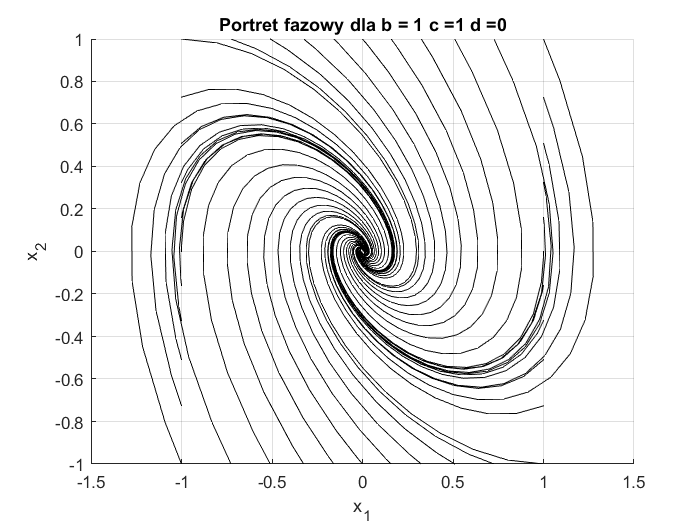

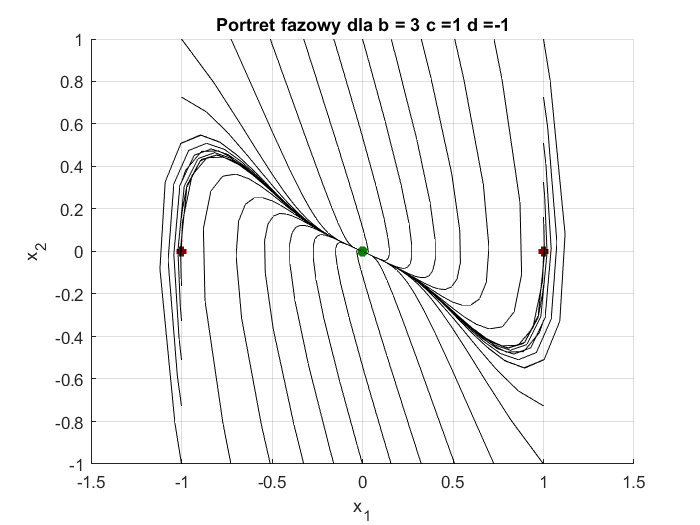

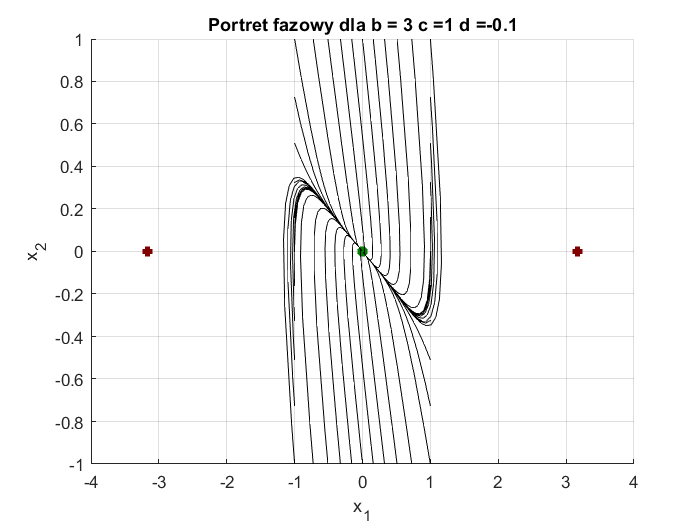

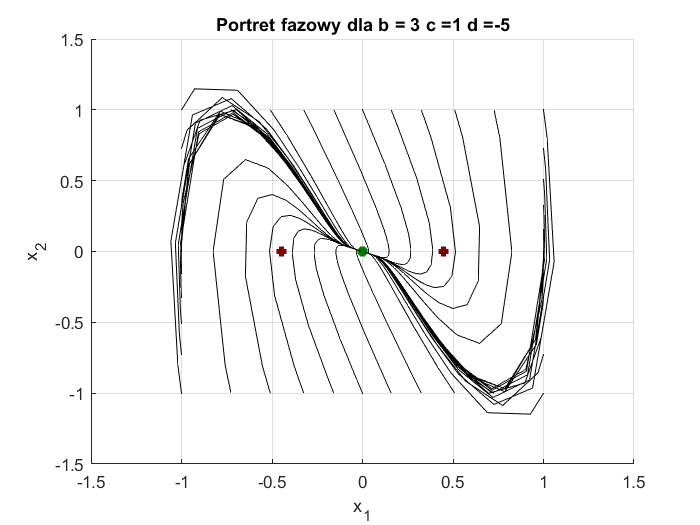

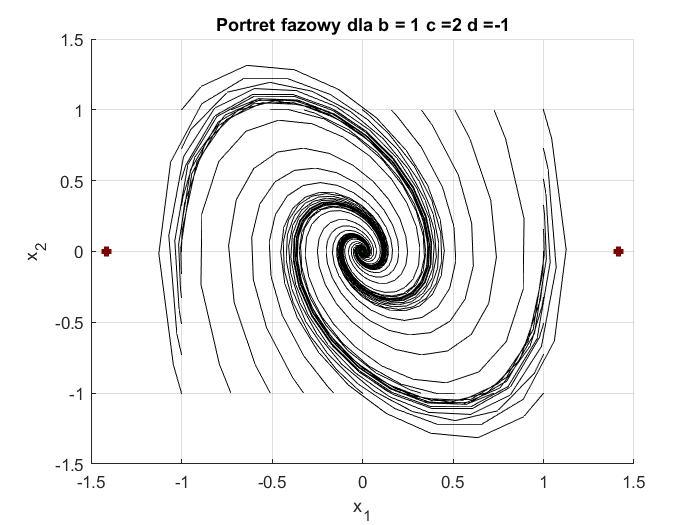

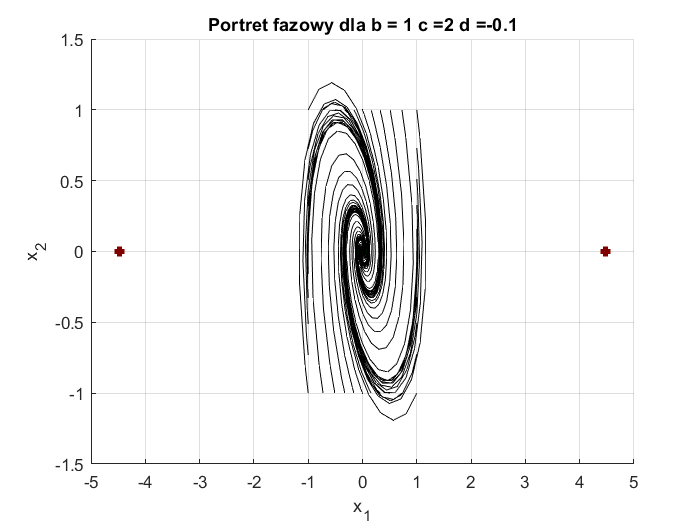

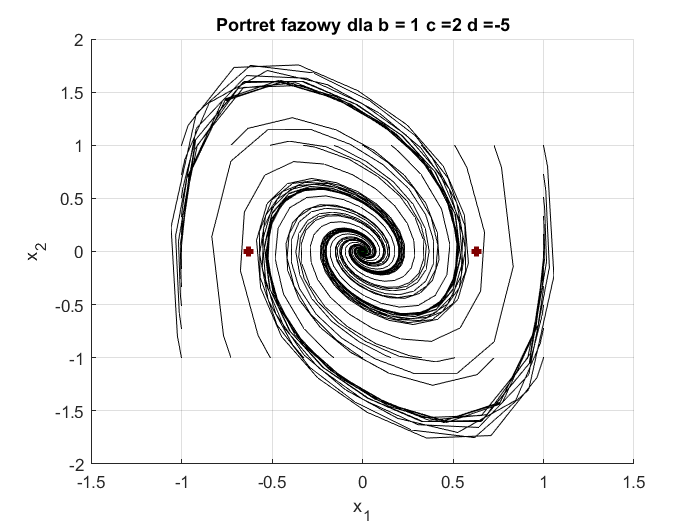

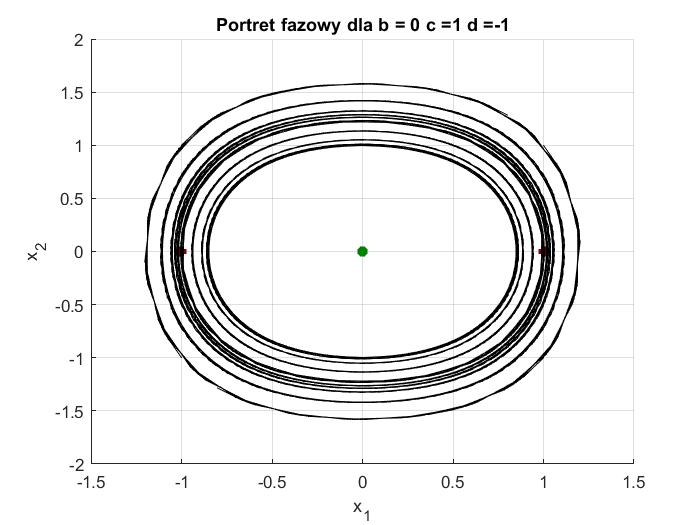

%Skrypt podobny do skryptu z cwiczenia dot układów liniowych, ale adaptowany do analizy stabilności
%z wykorzystaniem 1 metody Lapunova:
%Poniżej wpsiujemy parametry:
%parametry b,c>0:
%parametr d<0,
% |c|<|d|
%
B = [1,3,3,3,1,1,1,0,0.1]; %b>2sqrt(c) żeby układ liniowy (d=0) był aperiodyczny
C = [1,1,1,1,2,2,2,1,2];
D = [0,-1,-0.1,-5,-1,-0.1,-5,-1,-1]; %współcznynnik częsci nieliniowej wg równania z instrukcji. Powinien być < 0
for i=1:9
    b = B(i);
    c = C(i);
    d = D(i);
    T=10; %końcowy czas symulacji
    P=20; %ilość warunków początkowych do testu. Mniejsza ilość daje lepszą czytelność, ale większa ilość
    % pozwala dokładniej oszacować obszar przyciągania asymptotycznego.
    %pusty wykres:
    figure;hold on; grid on;
    %wrysowanie punktow równowagi na wykresie:
    if d<0
        %punkty niestabilne:
        plot(sqrt(-c/d),0,'+','linewidth',3,'color',[.5 0 0]);
        plot(-sqrt(-c/d),0,'+','linewidth',3,'color',[.5 0 0]);
        %punkt stabilny:
        plot(0,0,'*','linewidth',3,'color',[0 .5 0]);
    end
    %Wyznaczanie zbioru warunków poczatkowych obejmujących całą pł. fazową:
    a=0:(pi/P):(2*pi);
    X1=[cos(a);sin(a)];
    X2=X1./[max(abs(X1));max(abs(X1))];
    %
    M=size(X2,2);
    for m=1:M
        x0=X2(:,m);
        %tu wpisujemy nazwę funkcji z modelem układu n-l:
        out = sim('met_Lap_1_31', T);
        %plot(x1(:,1),x2(:,2),'k-');
        plot(out.x1,out.x2,'k-');
        %tu dodać resztę

    str = strcat("Portret fazowy dla b = ",num2str(b),' c = ',num2str(c),' d = ', num2str(d));
    title(str)
    xlabel('x_1');ylabel('x_2');
    end
end